Loops iterate over a block of code until they are done. This is a common program structure. For example, we may be iterating over all elements of an array and doing something with each element. Or, we may be iterating on a root-finding algorithm until it has found the root.

For loops iterate over an index. Here 1:5 is the range of integers from 1 to 5.

for i = 1:5
    disp(i)
end

     1

     2

     3

     4

     5



The range can be more complicated. This range iterates backwards by 0.2.

for v = 1.0:-0.2:0.0
    disp(v)
end

     1

    0.8000

    0.6000

    0.4000

    0.2000

     0



Usually we use a for loop when we are accesing an array. Here we simulate an AR(1) process and plot it

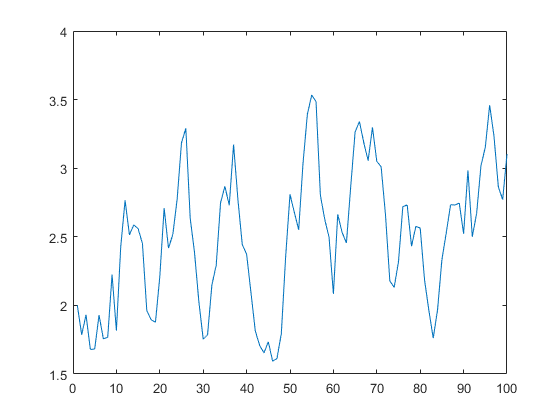

A = rand(100, 1);
B = zeros(100, 1);
B(1) = 2; % initial value
for i = 2:length(A)
    B(i) = 0.8*B(i - 1) + A(i);
end
plot(B)

A while loop iterates until some condition is true. Here we implement Bogosort, one of the worst sorting algorithms ever designed. It randomly permutes a list until it is sorted. It has an expected number of iterations of N! (N factorial).


done = false;
A = rand(6);
iter = 0;
while ~issorted(A)
    iter = iter + 1;
    inds = randperm(length(A));
    A = A(inds);
end
iter

iter = 1098

Of course, all of these constructs can be mixed.

A = 5

A = 5

for i = 1:5
    if i == 1
        while A < 10
            A = A + 1
        end
    end
    A = A + i
end

A = 6

A = 7

A = 8

A = 9

A = 10

A = 11

A = 13

A = 16

A = 20

A = 25